# **两次优化**

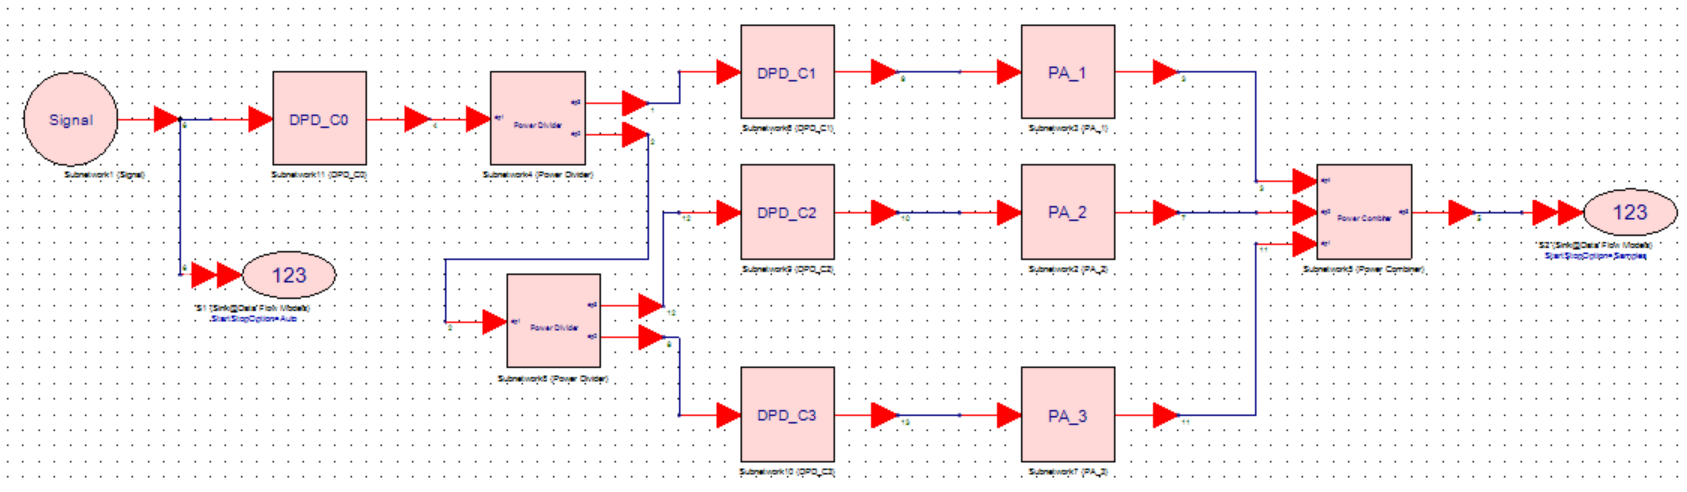

% 运行前请先将子文件夹添加到路径
clc;

## -----------------------------Model C Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
PA1_output = Data_matrix(:,3) + 1i * Data_matrix(:,4);
PA1_input = 0.5*Sys_input;
% 参数需要保持一致
M = 4;
PA1_flag = 1;
times = 8;
load('nmse_A1.mat', 'nmse_min');
[model_input,model_output] = pre_train(M,PA1_input,PA1_output,dim);
model_output_real = model_output(1,:);
model_output_imag = model_output(2,:);

---------- 1 ---------

本次训练迭代了 160.000000 轮


【PA1模型的拟合精度NMSE为 -47.986648 dB】


【回代系统后，PA1的NMSE为 -38.423940 dB】


---------- 2 ---------

本次训练迭代了 160.000000 轮


【PA1模型的拟合精度NMSE为 -49.919460 dB】


【回代系统后，PA1的NMSE为 -41.507145 dB】


---------- 3 ---------

本次训练迭代了 160.000000 轮


【PA1模型的拟合精度NMSE为 -47.539115 dB】


【回代系统后，PA1的NMSE为 -33.917972 dB】


---------- 4 ---------

本次训练迭代了 160.000000 轮


【PA1模型的拟合精度NMSE为 -50.206705 dB】


【回代系统后，PA1的NMSE为 -32.245381 dB】


---------- 5 ---------

本次训练迭代了 88.000000 轮


【PA1模型的拟合精度NMSE为 -42.115408 dB】


【回代系统后，PA1的NMSE为 -32.580459 dB】


---------- 6 ---------

本次训练迭代了 102.000000 轮


【PA1模型的拟合精度NMSE为 -46.957735 dB】


【回代系统后，PA1的NMSE为 -37.074647 dB】


---------- 7 ---------

本次训练迭代了 54.000000 轮


【PA1模型的拟合精度NMSE为 -42.258211 dB】


【回代系统后，PA1的NMSE为 -30.990423 dB】


---------- 8 ---------

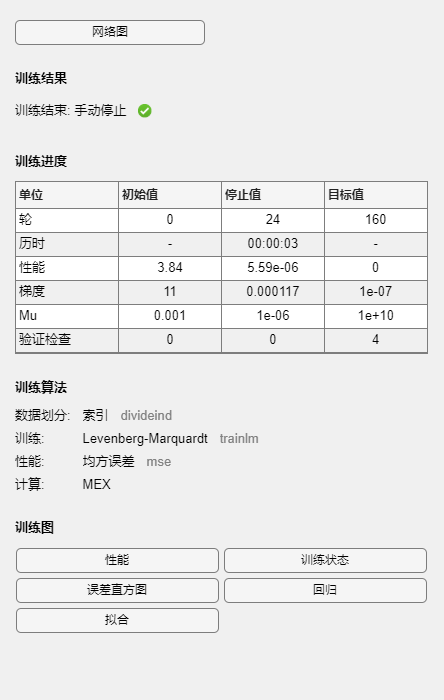

本次训练迭代了 24.000000 轮


【PA1模型的拟合精度NMSE为 -43.059965 dB】


【回代系统后，PA1的NMSE为 -34.133276 dB】


% 优化迭代
for ii=1:times
    fprintf('---------- %d ---------',ii);

    %% 训练PA1
    path_temp = 'Method_C\PA1\FNN_temp.mat';
    if (PA1_flag)
        % 模型训练
        [model,tr] = Train_sim(M,PA1_input,PA1_output,[32,16],0);
        fprintf('本次训练迭代了 %f 轮\n', tr.num_epochs);
        save(path_temp, 'model');
    end
    % 模型精度
    [model_input,model_output] = pre_train(M,PA1_input,PA1_output,dim);
    data = load(path_temp);
    DPD_output_m = sim(data.model,model_input);
    DPD_output = DPD_output_m(1,:)+1j*DPD_output_m(2,:);
    nmse = NMSE_dB(model_output(1,:)+1j*model_output(2,:), DPD_output);
    fprintf('【PA1模型的拟合精度NMSE为 %f dB】\n', nmse);

    %% 第一次迭代
    [A1_input,A23] = Power_Divider(Sys_input);
    A1_input_DPD = DPD_sim(A1_input,M,'Method_C\PA1\FNN_temp.mat');
    A1_output = PA_1(A1_input_DPD);
    % 评估
    nmse_PA1 = NMSE_dB(A1_input,A1_output);
    fprintf('【回代系统后，PA1的NMSE为 %f dB】\n', nmse_PA1);

    
    %% 保留最佳结果
    if(nmse_PA1<nmse_min)
        nmse_min=nmse_PA1;
        save('nmse_min.mat', 'nmse_min');
        %
        data = load('Method_C\PA1\FNN_temp.mat');
        model = data.model;
        save('Method_C\PA1\FNN_opt.mat', 'model');
    end
end

## -----------------------------Model C Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2);
% 参数需要保持一致
M = 4;

## Model Test

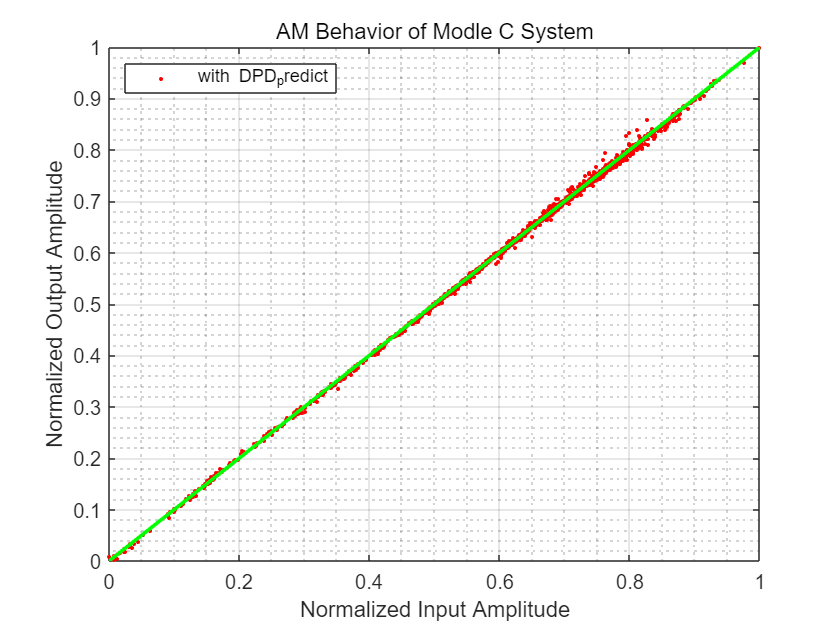

% 系统仿
[A1_input,A23] = Power_Divider(Sys_input);
A1_input_DPD = DPD_sim(A1_input,M,'Method_C\PA1\FNN_opt.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
% 由于PA和DPD的延时，所以少算（4+2M）个值
PA1_input = A1_input(5+M*2:end);
PA1_output = A1_output(5+M*2:end);
% 性能评估
Plot_AM(PA1_input,PA1_output,'AM Behavior of Modle C System','with DPD_predict');

nmse_now = NMSE_dB(PA1_input,PA1_output);
fprintf('回代系统，PA1的NMSE仿真结果为 %f dB\n', nmse_now);

回代系统，PA1的NMSE仿真结果为 -41.930464 dB
